# Filter Design %%

## Specifications Given %%

A_tilda_p = 0.10;  % dB max passband ripple
A_tilda_a = 55; %dB min stopband attenuation
wp1 = 500; %rad/s lower passband edge
wp2 = 800; %rad/s upper passband edge
wa1 = 400; %rad/s lower stopband edge
wa2 = 900; %rad/s upper stopband edge
ws = 2*(200+1000); %sampling freqency

## Derived Specifications %%

bt1 = wp1-wa1;  %lower transition width
bt2 = wa2-wp2;  % upper transisiton width
bt = min(bt1,bt2); %critical transition width
wc1 = wp1-bt/2; % lower cutoff frequency
wc2 = wp2+bt/2; % upper cutoff frequency
T = 2*pi/ws; % sampling period

## Kaiser Window %%

deltaP = (10^(0.05*A_tilda_p) - 1)/ (10^(0.05*A_tilda_p) + 1);
deltaA = 10^(-0.05*A_tilda_a);
delta = min(deltaP,deltaA);

Aa = -20*log10(delta);  % Actual stopband attenuation

if Aa<=21               % Calculating alpha 
    alpha = 0;
elseif Aa>21 && Aa<= 50
    alpha = 0.5842*(Aa-21)^0.4 + 0.07886*(Aa-21);
else
    alpha = 0.1102*(Aa-8.7);
end

if Aa <= 21             % Calculating D
    D = 0.9222;
else
    D = (Aa-7.95)/14.36;
end

N = ceil(ws*D/bt +1);
if mod(N,2) == 0
    N = N+1;
end

n = -(N-1)/2:1:(N-1)/2;   % length of the filter

beta = alpha*sqrt(1-(2*n/(N-1)).^2);

## generate I(alpha) %%

bessellimit = 50;

Ialpha = 1;
for k = 1:bessellimit
    termk = (1/factorial(k)*(alpha/2).^k).^2;
    Ialpha = Ialpha + termk;
end

## generate I(beta) %%

Ibeta = 1;
k = 1;
for k = 1:bessellimit
    termk = (1/factorial(k)*(beta/2).^k).^2;
    Ibeta = Ibeta + termk;
end

## window

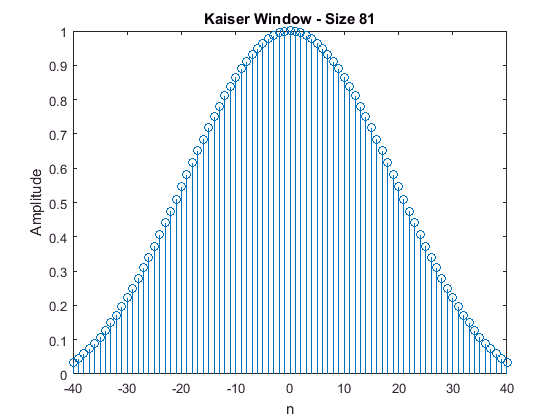

wknt = Ibeta/Ialpha;

figure
stem(n,wknt)
xlabel('n')
ylabel('Amplitude')
title(strcat(['Kaiser Window - Size',' ', num2str(N)]));

## impulse response %%

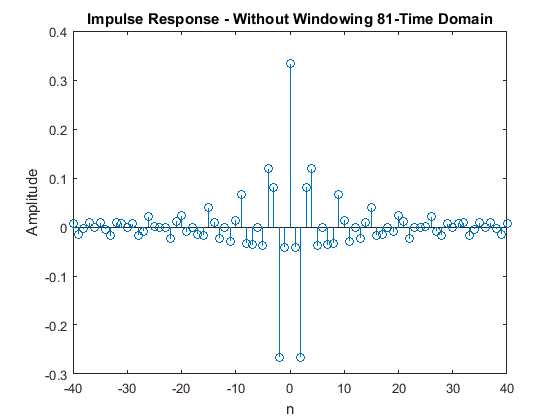

nleft = -(N-1)/2:-1;
hntleft = 1./(nleft*pi).*(sin(wc2*nleft*T)-sin(wc1*nleft*T));

nright = 1:(N-1)/2;
hntright = 1./(nright*pi).*(sin(wc2*nright*T)-sin(wc1*nright*T));

hnt0 = 2/ws*(wc2-wc1);

hnt = [hntleft,hnt0,hntright];
figure
stem(n,hnt)
xlabel('n')
ylabel('Amplitude')
title(strcat(['Impulse Response - Without Windowing',' ', num2str(N),'-Time Domain']));


figure
[h,w] = freqz(hnt);
w = w/T;
h = 20*log10(h);
plot(w,h)

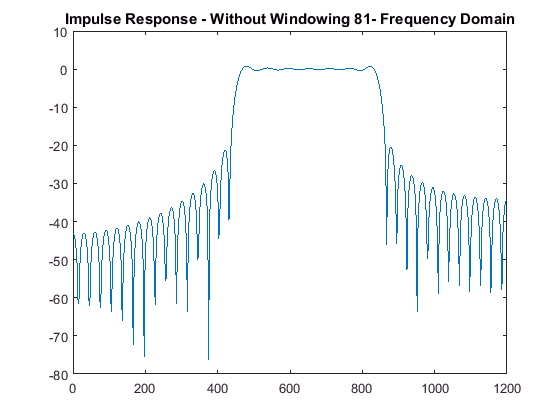

title(strcat(['Impulse Response - Without Windowing',' ', num2str(N),'- Frequency Domain']));

## filter %%

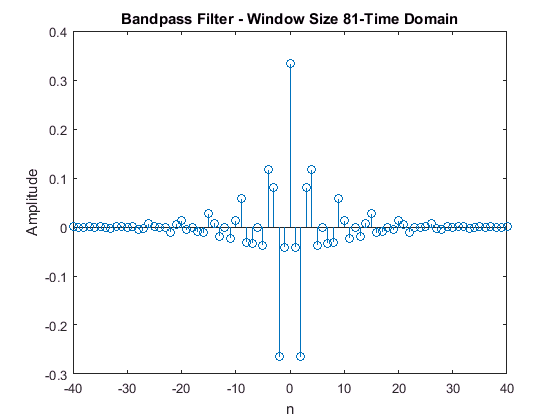

filter = hnt.*wknt;
figure
stem(n,filter)
xlabel('n')
ylabel('Amplitude')
title(strcat(['Bandpass Filter - Window Size',' ', num2str(N),'-Time Domain']));


figure
[h,w] = freqz(filter);
w = w/T;
h = 20*log10(h);
plot(w,h)

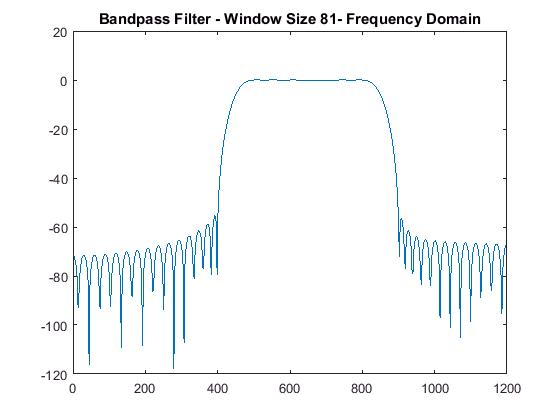

title(strcat(['Bandpass Filter - Window Size',' ', num2str(N), '- Frequency Domain']));

## input signal generation %%

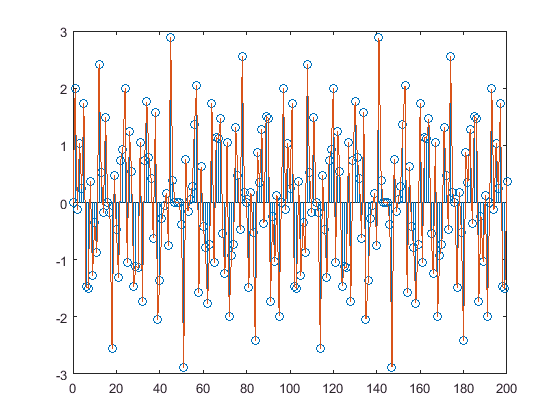

w1 = wc1/2;
w2 = wc1 + (wc2-wc1)/2;
w3 = wc2 + (ws/2-wc2)/2;
wi = [w1,w2,w3];
xnt = 0;
xdash =0;
n1 = 0:1:200;
for each = wi
    xnt = xnt+ sin(each.*n1.*T);
    xdash = xdash+sin(each.*n1.*T);
end

figure
stem(n1,xnt)
hold on
plot(n1,xdash)

## filtering the generated signal using frequency domain multiplication %%

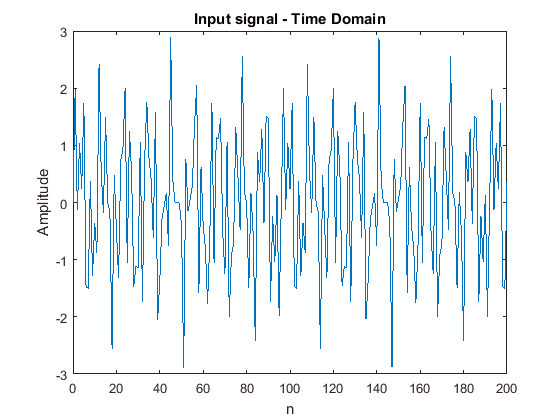

% xnt before filtering 

figure
plot(n1,xnt)
xlabel('n')
ylabel('Amplitude')
title(strcat(['Input signal',' ','- Time Domain']));


figure
[h,w] = freqz(xnt);
w = w/T;
plot(w,h)

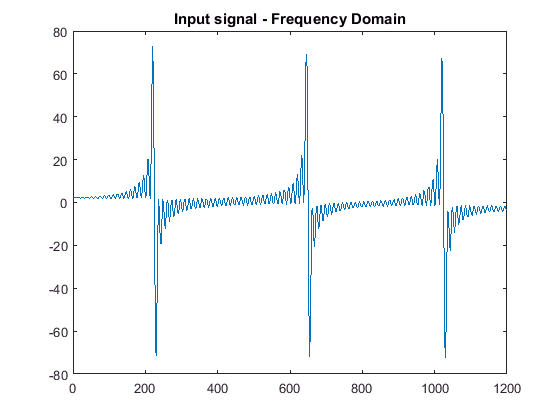

title(strcat(['Input signal',' ','- Frequency Domain']));

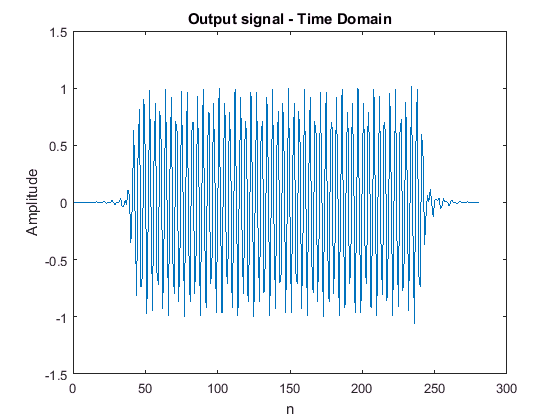



Npoint = length(xnt) + length(filter) - 1;  % length for fft in x dimension
xfft = fft(xdash,Npoint);
filterfft = fft(filter,Npoint);
outfft = filterfft .* xfft;
out = ifft(outfft,Npoint);



figure
plot(out)
% hold on
% plot(sin(n1*w2*T));
xlabel('n')
ylabel('Amplitude')
title(strcat(['Output signal',' ','- Time Domain']));


figure
[h,w] = freqz(out);
w = w/T;
plot(w,h)

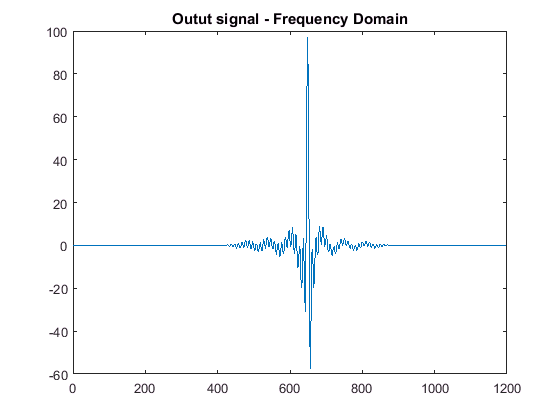

title(strcat(['Outut signal',' ','- Frequency Domain']));